姓名：庄璧如 学号：111321534

ex1 tanh function

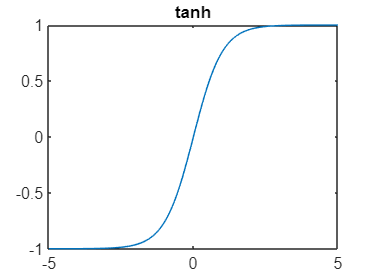

x=-5:0.1:5;
y=((exp(x)-exp(-x))./(exp(x)+exp(-x)));
plot(x,y),title('tanh')

calculate differenciation

syms x
f=(exp(x)-exp(-x))./(exp(x)+exp(-x));
df=diff(f)

$$df = 1-\frac{{\left({\mathrm{e}}^{-x}-{\mathrm{e}}^{x}\right)}^{2}}{{\left({\mathrm{e}}^{-x}+{\mathrm{e}}^{x}\right)}^{2}}$$

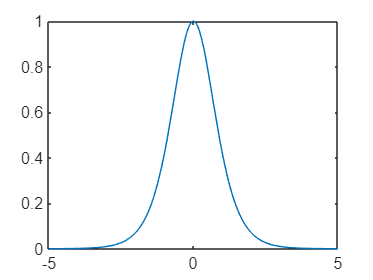

fplot(df)

sigmoid function

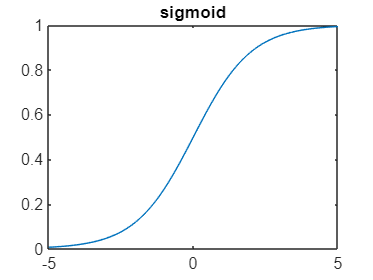

x=-5:0.1:5;
y=1./(1+exp(-x*1));
plot(x,y),title('sigmoid')

calculate differenciation

syms x
f2=1./(1+exp(-x*1));
df2=diff(f2)

$$df2 = \frac{{\mathrm{e}}^{-x}}{{\left({\mathrm{e}}^{-x}+1\right)}^{2}}$$

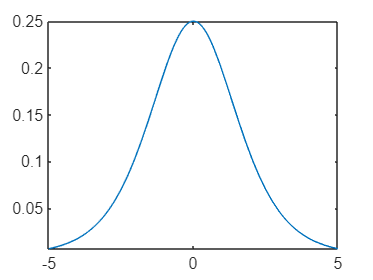

fplot(df2)

ex2 Gradient descent algorithm

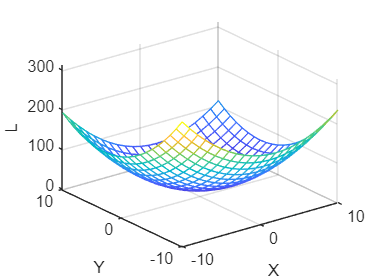

[X,Y]=meshgrid(-10:10,-10:10);
L=(X-2).^2+(Y-3).^2;
mesh(X,Y,L)
xlabel('X'),ylabel('Y'),zlabel('L');

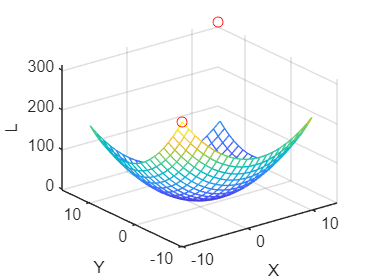

hold on
x(1)=-10;
y(1)=-10;
L(1)=(x(1)-2).^2+(y(1)-3).^2;
plot3(x(1),y(1),L(1),'or');
l=0.05;
for i=2:100
    dx=2*(x(i-1)-2);
    dy=2*(y(i-1)-3);
    x(i)=x(i-1)-1*dx;
    y(i)=y(i-1)-1*dy;
    L(i)=(x(i)-2).^2+(y(i)-3).^2;
    plot3(x(i),y(i),L(i),'or');
end